%% Exp1 and Exp2: potterior probabilities and participant contrasts 
% All parameter values are prior values set for experiment design, which
% might not be the same as the fitted value of parameters
clear; clc;
% experiment 1
paramValues(1).mentalizing = 5;
paramValues(1).vt = [5 1];
paramValues(1).dw = [5 1 5];
paramValues(1).kw = [5 1];
% experiment 2
paramValues(2).mentalizing = 5;
paramValues(2).vt = [5 1];
paramValues(2).dw = [5 1 5];
paramValues(2).kw = [5 1];
% Adjust the display order in Exp2 
trialOrder = {[1 2 3 4 7 8 5 6], [4 3 2 1 8 7 6 5]};
% Load the data
data = { '/Users/foxxis/Documents/social induction/experiment data/exp1/output100.xlsx',...
         '/Users/foxxis/Documents/social induction/experiment data/exp2/final_data.csv'};
behaviorColumns = {{'d1','d2','d3','d4','d5','d6','d7','d8'}, ...
                   {'p1','p2','p3','p4','p5','p6','p7','p8'}};
saveFigure = true;
root = fileparts(fileparts(fileparts(mfilename('fullpath'))));
outputDir = fullfile(root, 'figures', 'exp1_exp2_paired');

%% Compute each trial's posterior
results = struct([]);
allContrasts = [];
for experiment = 1:2
    names = {'mentalizing','vt','dw','kw'};
    counts = [1 2 3 2];
    order = trialOrder{experiment};
    %calculate the posterior
    rawWeights = modelWeights(experiment, paramValues(experiment));
    assert(all(isfinite(rawWeights(:))) && all(rawWeights(:)>=0 & rawWeights(:)<=1));
    weights = rawWeights;
    weights = weights(order,:);
    contrasts = weights(1:2:8,:) - weights(2:2:8,:);
    %read the original data
    tbl = readtable(data{experiment});
    columns = behaviorColumns{experiment};
    ratings = table2array(tbl(:,columns));
    if ~isnumeric(ratings), ratings = str2double(string(ratings)); end
    validateattributes(ratings, {'numeric'}, {'real','2d','ncols',8,'nonempty'});
    valid = isfinite(ratings) & ratings>=1 & ratings<=6 & ratings==fix(ratings);
    if any(~valid(:))
        warning('Exp%d: excluding %d invalid or missing ratings.',experiment,nnz(~valid));
    end
    %change the rating into 0-1 scale
    probabilities = (ratings-0.5)/6;
    probabilities(~valid) = NaN;
    probabilities = probabilities(:,order);
    observed = probabilities(:,1:2:8)-probabilities(:,2:2:8);
    results(experiment).rawWeights = rawWeights;
    results(experiment).trialOrder = order;
    results(experiment).weights = weights;
    results(experiment).contrasts = contrasts;
    results(experiment).rawRatings = ratings;
    results(experiment).ratings = ratings(:,order);
    results(experiment).probabilities = probabilities;
    results(experiment).observed = observed;
    results(experiment).pairCounts = sum(isfinite(observed),1);
    fprintf('Exp%d valid counts: %d %d %d %d\n',experiment,results(experiment).pairCounts);
    displayed = contrasts(:,1:2);
    allContrasts = [allContrasts; displayed(:); observed(isfinite(observed))]; %#ok<AGROW>
end

Exp1 valid counts: 101 101 101 101
Exp2 valid counts: 87 87 87 87


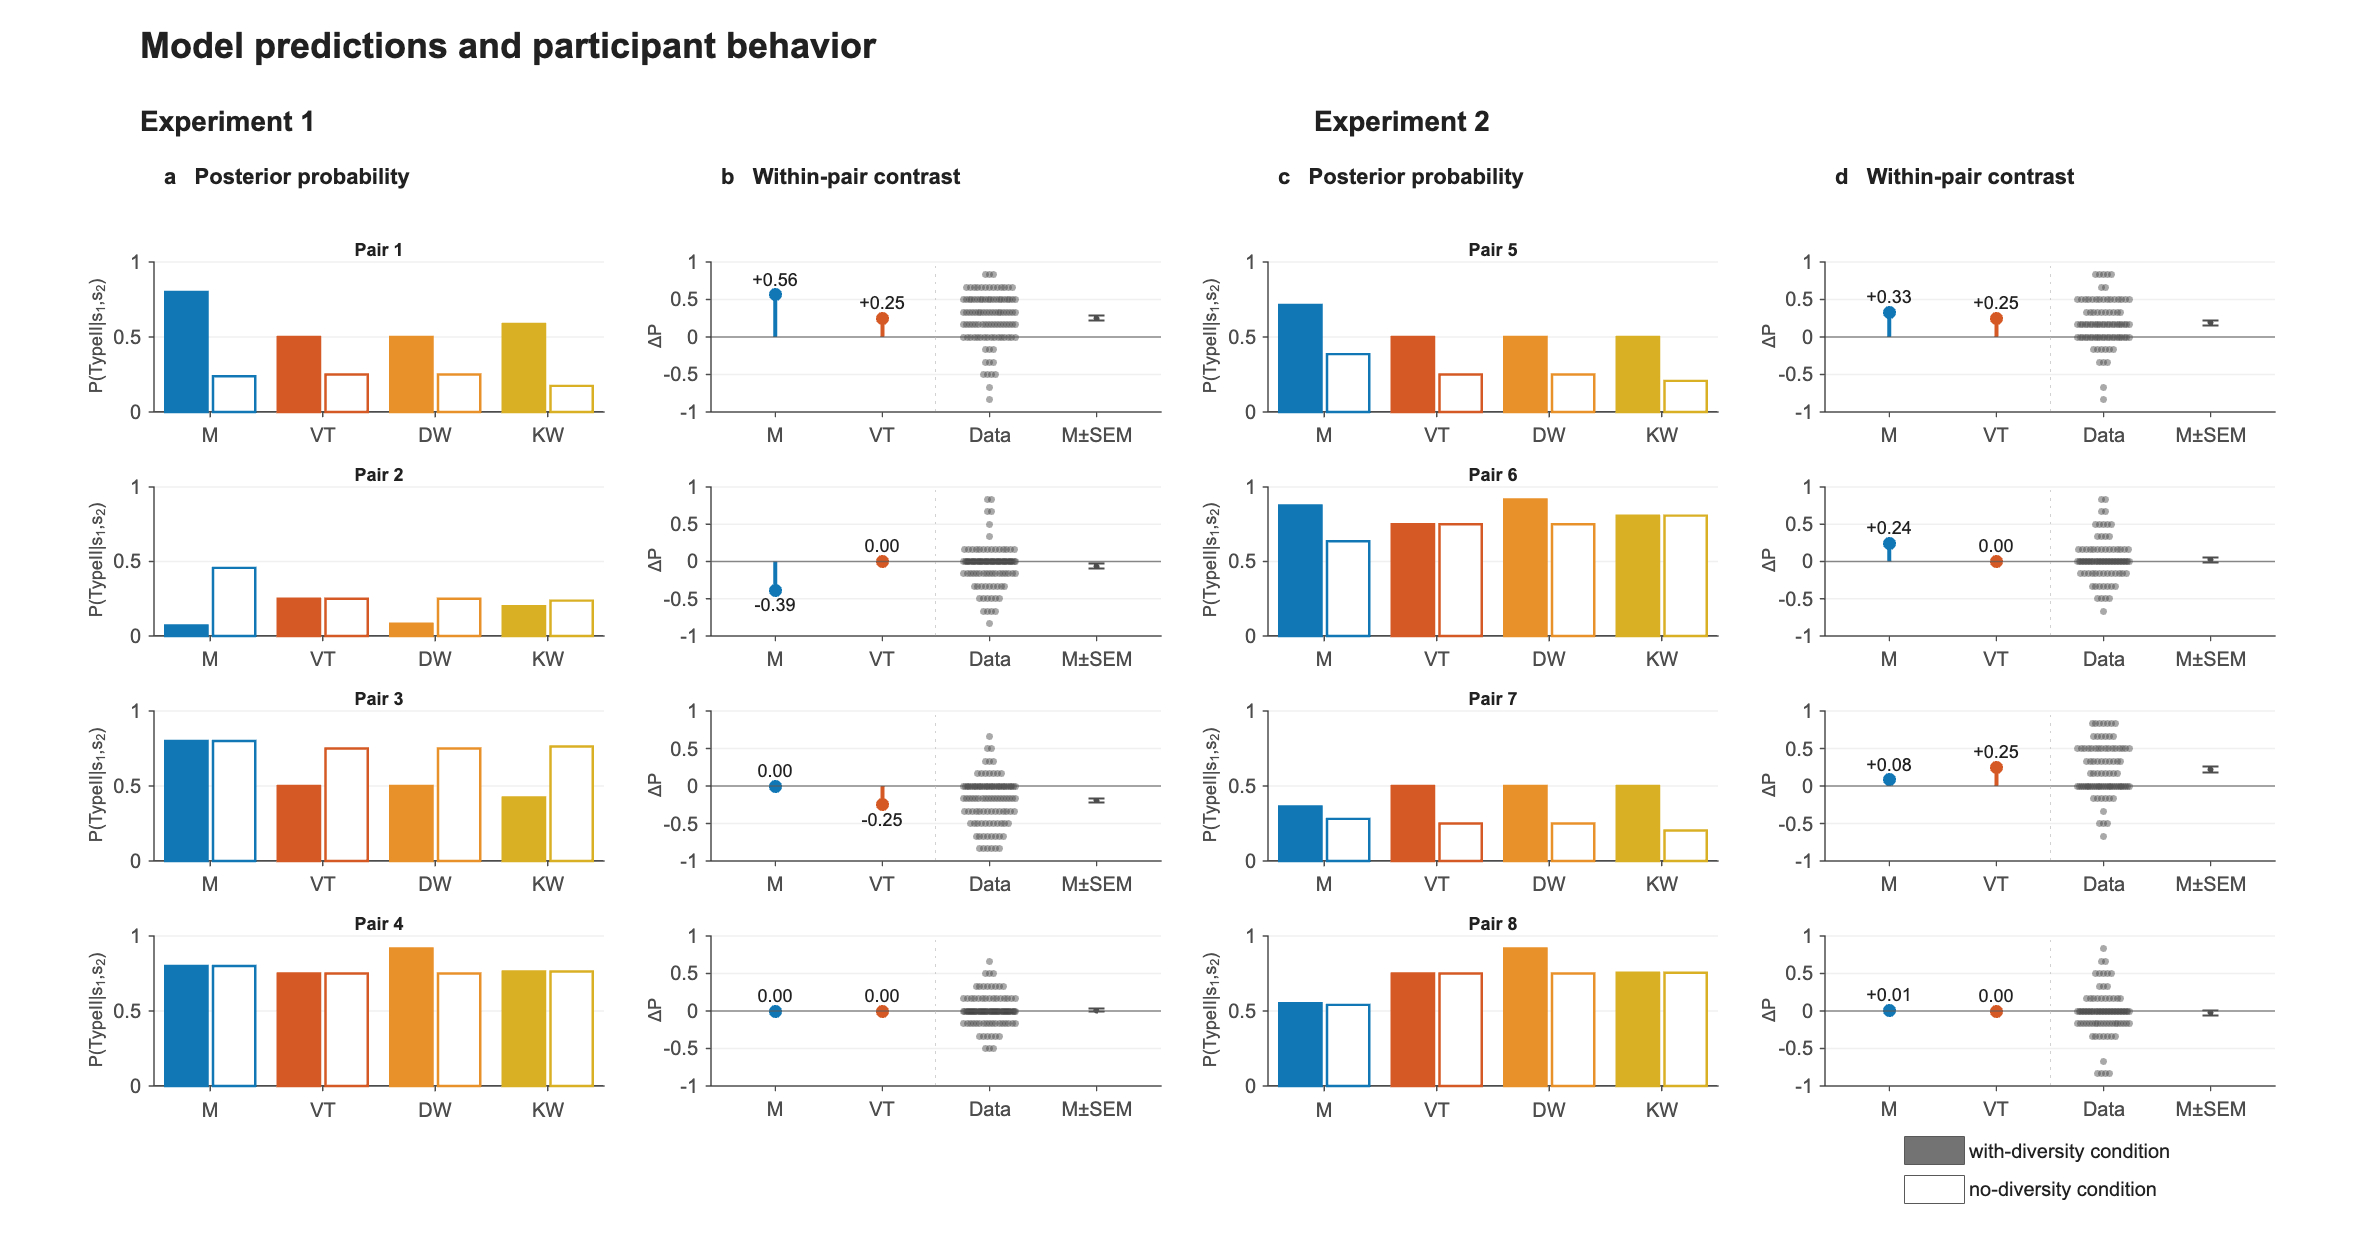

deltaLimit = max(1,ceil((max(abs(allContrasts))+0.16)*10)/10);

%% Plots including four columns, Exp1 posterior / contrast / Exp2 posterior / contrast
colors = [
    0.070  0.465  0.710;   
    0.830  0.350  0.140;  
    0.910  0.570  0.170;  
    0.850  0.685  0.140    
];
labels = {'M','VT','DW','KW'};
fig = figure('Color','w','Name','Experiments 1 and 2: paired posteriors', ...
    'Position',[40 40 1580 1050]);
set(fig,'DefaultAxesFontName','Arial','DefaultTextFontName','Arial');
heading(fig,[.055 .95 .90 .035],'Model predictions and participant behavior',18);
heading(fig,[.055 .89 .42 .03],'Experiment 1',14);
heading(fig,[.55 .89 .42 .03],'Experiment 2',14);
left  = [.065 .300 .535 .770];
width = [.19 .19 .19 .19];
columnTitles = {'a   Posterior probability','b   Within-pair contrast', ...
                'c   Posterior probability','d   Within-pair contrast'};
for column = 1:4
    heading(fig,[left(column) .843 width(column)+.025 .03],columnTitles{column},11);
end

for pair = 1:4
    trials = [2*pair-1 2*pair];
    bottom = .67-(pair-1)*.18;
    for experiment = 1:2
        column = 2*experiment-1;
        r = results(experiment);
        sourceTrials = r.trialOrder(trials);
        ax = axes(fig,'Position',[left(column) bottom width(column) .12]);
        hold(ax,'on');
        barX = 1 + (0:3)*0.8;
        for k = 1:4
            bar(ax,barX(k)-.17,r.weights(trials(1),k),.30, ...
                'FaceColor',colors(k,:), ...
                'EdgeColor',colors(k,:),'LineWidth',1.2);
            bar(ax,barX(k)+.17,r.weights(trials(2),k),.30, ...
                'FaceColor','w', ...
                'EdgeColor',colors(k,:),'LineWidth',1.2 ...
                );
        end
        styleAxes(ax,labels);
        xticks(ax,barX);
        xlim(ax,[barX(1)-.4, barX(end)+.4]);
        ylim(ax,[0 1]);
        yticks(ax,[0 .5 1]);
       
        probabilityLabel = 'P(TypeII|s_1,s_2)';
        deltaLabel = '\DeltaP';
       
        ylabel(ax,probabilityLabel,'Interpreter','tex','FontName','Arial','FontSize',9);
        ax.YLabel.Units = 'normalized';
        ax.YLabel.Position = [-0.10 0.5 0];
        title(ax,sprintf('Pair %d', pair + 4*(experiment==2)),'FontSize',9);

        if pair==1 && experiment==1
            h1 = patch(ax,NaN,NaN,[.45 .45 .45],'EdgeColor',[.35 .35 .35]);
            h2 = patch(ax,NaN,NaN,'w','EdgeColor',[.35 .35 .35]);
            lg = legend(ax,[h1 h2], ...
                {'with-diversity condition','no-diversity condition'}, ...
                'Orientation','vertical','Box','off','FontSize',10, ...
                'FontName','Arial','Interpreter','none','AutoUpdate','off');
            set(lg,'Units','normalized','Position',[.75 .035 .22 .055]);
        end
        column = column+1;
        ax = axes(fig,'Position',[left(column) bottom width(column) .12]);
        hold(ax,'on'); yline(ax,0,'-','Color',[.35 .35 .35],'LineWidth',.8);
        for k = 1:2
            value = r.contrasts(pair,k);
            plot(ax,[k k],[0 value],'-','Color',colors(k,:),'LineWidth',2);
            plot(ax,k,value,'o','MarkerSize',6,'MarkerFaceColor',colors(k,:), ...
                'MarkerEdgeColor',colors(k,:));
            if abs(value)<.005, txt='0.00'; else, txt=sprintf('%+.2f',value); end
            if value>=-1e-6, offset=.07; align='bottom'; else, offset=-.07; align='top'; end
            text(ax,k,value+offset,txt,'HorizontalAlignment','center', ...
                'VerticalAlignment',align,'FontName','Arial','FontSize',9);
        end
        observed = r.observed(:,pair);
        observed = observed(isfinite(observed));
        x = 3*ones(size(observed));
        [~,~,groups] = unique(round(observed*6));
        for group = 1:max([0;groups])
            members = find(groups==group);
            if numel(members)>1
                spread = min(.24,.018*(numel(members)-1));
                x(members) = 3+linspace(-spread,spread,numel(members))';
            end
        end
        scatter(ax,x,observed,12,[.25 .25 .25],'filled', ...
            'MarkerFaceAlpha',.45,'MarkerEdgeColor','none');
        % Mean ± SEM of participants' within-pair differences
        nObs = numel(observed);
        meanDelta = mean(observed);
        semDelta = std(observed,0) / sqrt(nObs);
        meanColor = [0.30 0.30 0.30];
        errorbar(ax,4,meanDelta,semDelta,'o', ...
            'Color',meanColor,'LineStyle','none','LineWidth',1, ...
            'CapSize',8,'MarkerSize',2, ...
            'MarkerFaceColor',meanColor, ...
            'MarkerEdgeColor',meanColor);
        xline(ax,2.5,':','Color',[.75 .75 .75]);
        styleAxes(ax,{'M','VT','Data','M±SEM'});
        xlim(ax,[0.4 4.6]);
        ylim(ax,[-deltaLimit deltaLimit]); yticks(ax,[-1 -.5 0 .5 1]);
        ylabel(ax,deltaLabel,'Interpreter','tex','FontName','Arial','FontSize',9);
        ax.YLabel.Units = 'normalized';
        ax.YLabel.Position = [-0.10 0.5 0];
    end
end

set(fig,'Visible','on');

ANOVA

within = table( ...
    categorical(["Yes"; "No"; "Yes"; "No"]), ...
    categorical(["Yes"; "Yes"; "No"; "No"]), ...
    'VariableNames', {'Vote', 'Mentalizing'});

effectRows = { ...
    '(Intercept):Vote'; ...
    '(Intercept):Mentalizing'; ...
    '(Intercept):Vote:Mentalizing'};

errorRows = { ...
    'Error(Vote)'; ...
    'Error(Mentalizing)'; ...
    'Error(Vote:Mentalizing)'};

for experiment = 1:2

    % Signed differences, with the same direction as the figure.
    % Multiplying by 6 returns differences to original rating units;
    % it does not change F, p, or partial eta squared.
    D = 6 * results(experiment).observed;

    % Exp1 Pair 1: Trial 1 and Trial 2 are both represented as 1-P.
    % Therefore, (1-P1)-(1-P2) = -(P1-P2).
    if experiment == 1
        D(:,1) = -D(:,1);
    end

    % Use participants with valid data in all four pairs.
    included = all(isfinite(D), 2);
    D = D(included, :);
    N = size(D, 1);
    assert(N >= 2, 'Not enough complete participants.');

    T = array2table(D, ...
        'VariableNames', {'Pair1','Pair2','Pair3','Pair4'});

    rm = fitrm(T, 'Pair1-Pair4 ~ 1', ...
        'WithinDesign', within);

    aov = ranova(rm, 'WithinModel', 'Vote*Mentalizing');

    % Extract the two main effects and interaction.
    Effect = ["Vote"; "Mentalizing"; "Vote × Mentalizing"];
    F = nan(3,1);
    df1 = nan(3,1);
    df2 = nan(3,1);
    p = nan(3,1);
    eta_p2 = nan(3,1);

    for j = 1:3
        F(j) = aov{effectRows{j}, 'F'};
        df1(j) = aov{effectRows{j}, 'DF'};
        df2(j) = aov{errorRows{j}, 'DF'};
        p(j) = aov{effectRows{j}, 'pValue'};

        SS_effect = aov{effectRows{j}, 'SumSq'};
        SS_error = aov{errorRows{j}, 'SumSq'};
        eta_p2(j) = SS_effect / (SS_effect + SS_error);
    end

    anovaSummary = table(Effect, F, df1, df2, p, eta_p2);

    % Descriptive statistics for the same included participants.
    Pair = (1:4)' + 4*(experiment-1);
    Mean = mean(D,1)';
    SD = std(D,0,1)';
    SEM = SD / sqrt(N);

    pairSummary = table(Pair, repmat(N,4,1), Mean, SD, SEM, ...
        'VariableNames', {'Pair','N','Mean','SD','SEM'});

    fprintf('\nExperiment %d: N = %d; excluded = %d\n', ...
        experiment, N, sum(~included));
    disp(anovaSummary);
    disp(pairSummary);

    results(experiment).anova = anovaSummary;
    results(experiment).anovaFull = aov;
    results(experiment).pairStatistics = pairSummary;
    results(experiment).anovaIncluded = included;
end


Experiment 1: N = 101; excluded = 0


           Effect              F        df1    df2        p           eta_p2  
    ____________________    ________    ___    ___    __________    __________

    "Vote"                    39.502     1     100    8.6211e-09       0.28317
    "Mentalizing"               5.61     1     100      0.019781       0.05312
    "Vote × Mentalizing"    0.065369     1     100       0.79873    0.00065326



    Pair     N       Mean        SD        SEM  
    ____    ___    ________    ______    _______

     1      101     -1.5149    2.0426    0.20325
     2      101    -0.36634    1.7072    0.16987
     3      101     -1.1683    1.9135     0.1904
     4      101    0.059406    1.2556    0.12493




Experiment 2: N = 87; excluded = 0


           Effect              F       df1    df2        p          eta_p2  
    ____________________    _______    ___    ___    __________    _________

    "Vote"                   33.642     1     86     1.0751e-07      0.28119
    "Mentalizing"           0.12072     1     86        0.72911    0.0014017
    "Vote × Mentalizing"     1.1548     1     86        0.28555      0.01325



    Pair    N       Mean        SD        SEM  
    ____    __    ________    ______    _______

     5      87      1.1379    1.8688    0.20036
     6      87     0.13793    1.6993    0.18219
     7      87      1.3103    2.0647    0.22136
     8      87    -0.14943    1.8206    0.19519



%% One-sample t-tests against zero

for experiment = 1:2

    % Signed within-pair differences on the original 1-6 rating scale
    D = 6 * results(experiment).observed;

    % Exp1 Pair 1: reverse sign to match the reported direction
    if experiment == 1
        D(:,1) = -D(:,1);
    end

    % Use participants with valid data in all four pairs
    included = all(isfinite(D), 2);
    D = D(included, :);

    N = size(D,1);

    % Preallocate
    Pair   = (1:4)' + 4*(experiment-1);
    Mean   = mean(D,1)';
    SD     = std(D,0,1)';

    tStat  = nan(4,1);
    df     = nan(4,1);
    p      = nan(4,1);
    ciLow  = nan(4,1);
    ciHigh = nan(4,1);

    % One-sample t-test for each pair against zero
    for pair = 1:4
        x = D(:,pair);

        [~, p(pair), ci, stats] = ttest(x, 0);

        tStat(pair)  = stats.tstat;
        df(pair)     = stats.df;
        ciLow(pair)  = ci(1);
        ciHigh(pair) = ci(2);
    end

    % Summary table
    ttestSummary = table( ...
        Pair, repmat(N,4,1), Mean, SD, ...
        tStat, df, p, ciLow, ciHigh, ...
        'VariableNames', ...
        {'Pair','N','Mean','SD','t','df','p','CI_Lower','CI_Upper'});

    fprintf('\nExperiment %d: One-sample t-tests against zero\n', experiment);
    disp(ttestSummary);

    % Store results
    results(experiment).ttest = ttestSummary;

end


Experiment 1: One-sample t-tests against zero


    Pair     N       Mean        SD         t       df         p         CI_Lower    CI_Upper 
    ____    ___    ________    ______    _______    ___    __________    ________    _________

     1      101     -1.5149    2.0426    -7.4532    100    3.3382e-11     -1.9181      -1.1116
     2      101    -0.36634    1.7072    -2.1566    100      0.033437    -0.70335    -0.029318
     3      101     -1.1683    1.9135    -6.1362    100    1.7078e-08     -1.5461     -0.79057
     4      101    0.059406    1.2556     0.4755    100       0.63547    -0.18846      0.30727




Experiment 2: One-sample t-tests against zero


    Pair    N       Mean        SD         t        df        p        CI_Lower    CI_Upper
    ____    __    ________    ______    ________    __    _________    ________    ________

     5      87      1.1379    1.8688      5.6796    86    1.799e-07     0.73964     1.5362 
     6      87     0.13793    1.6993     0.75708    86      0.45107    -0.22425    0.50011 
     7      87      1.3103    2.0647      5.9195    86    6.436e-08      0.8703     1.7504 
     8      87    -0.14943    1.8206    -0.76554    86      0.44605    -0.53745     0.2386 



Helper Functions

function w = modelWeights(experiment,p)
% Explicit experiment-specific weight formulas from src/models/*_model.m.
w = zeros(8,4);
% For Mentalizing
if experiment==1
    w(:,1) = [0.80000000; 0.23809524; 0.07142857; 0.45714286; 0.80000000; 0.80000000; 0.80000000; 0.80000000];
else
    w(:,1) = [00.6359223; 0.8769231; 0.3858696; 0.7142857; 0.5409836; 0.5526316; 0.2807018; 0.3636364];
end
% For VT
n=p.vt(2); 
denom = 2 + 2 * n;
if experiment==1
    w(:,2) = [0.5; 1/denom; 1/denom; 1/denom; (1+2*n)/denom; (1+2*n)/denom; 0.5; (1+2*n)/denom];
else
    w(:,2)=[(1+2*n)/denom; (1+2*n)/denom; 1/denom; 0.5; (1+2*n)/denom; (1+2*n)/denom; 1/denom; 0.5];
end
% For DW
n=p.dw(2); 
e=p.dw(3);
denom_n  = 2 + 2 * n;
denom_ne = 2 + 2 * n * e;
if experiment==1
    w(:,3) = [0.5; 1/denom_n;1/denom_ne;1/denom_n;(1+2*n*e)/denom_ne;(1+2*n)/denom_n;0.5;(1+2*n)/denom_n];
else
    w(:,3)= [(1+2*n)/denom_n; (1+2*n*e)/denom_ne; 1/denom_n; 0.5; ...
           (1+2*n)/denom_n; (1+2*n*e)/denom_ne; 1/denom_n; 0.5];
end
% For KW
n=p.kw(2); 
if experiment==1
    d_blue   = [1.870504, 1.108434, 1.108434, 1.108434];
    d_yellow = [3.085106, 1.870504, 1.108434, 1.870504];
    w(:,4)=[ (1 + d_yellow(1)*n) / (2 + (d_blue(1) + d_yellow(1))*n); ...
    1 / (2 + 2*d_blue(1)*n); ...
    1 / (2 + (d_blue(2) + d_yellow(2))*n); ...
    1 / (2 + 2*d_blue(2)*n); ...
    (1 + (d_blue(3) + d_yellow(3))*n) / (2 + (d_blue(3) + d_yellow(3))*n); ...
    (1 + 2*d_blue(3)*n) / (2 + 2*d_blue(3)*n); ...
    (1 + d_blue(4)*n) / (2 + (d_blue(4) + d_yellow(4))*n); ...
    (1 + 2*d_blue(4)*n) / (2 + 2*d_blue(4)*n) ...
];
else
    d_blue   = [1.604278, 1.604278, 1.410604, 1.410604, 1.040060, 1.040060, 1.463840, 1.463840];
    d_yellow = [1.604278, 1.604278, 1.410604, 1.410604, 1.040060, 1.040060, 1.463840, 1.463840];
    w(:,4) = [(1 + d_blue(1)*2*n) / (2 + d_blue(1)*2*n);...
    (1 + (d_blue(2) + d_yellow(2))*n) / (2 + (d_blue(2) + d_yellow(2))*n);...
    1 / (2 + d_yellow(3)*2*n);...
    (1 + d_blue(4)*n) / (2 + (d_yellow(4) + d_blue(4))*n);...
    (1 + d_blue(5)*2*n) / (2 + d_blue(5)*2*n);...
    (1 + (d_blue(6) + d_yellow(6))*n) / (2 + (d_blue(6) + d_yellow(6))*n);...
    1 / (2 + d_blue(7)*2*n);...
    (1 + d_yellow(8)*n) / (2 + (d_yellow(8) + d_blue(8))*n)];
end
end

function heading(fig,position,txt,size)
annotation(fig,'textbox',position,'String',txt,'EdgeColor','none', ...
    'FontName','Arial','FontSize',size,'FontWeight','bold');
end

function styleAxes(ax,labels)
set(ax,'FontName','Arial','FontSize',10,'Color','w','Box','off','LineWidth',.65, ...
    'TickDir','out','XColor',[.3 .3 .3],'YColor',[.3 .3 .3], ...
    'XGrid','off','YGrid','on','GridColor',[.85 .85 .85],'GridAlpha',.4);
xlim(ax,[-0.2 numel(labels)+.6]); xticks(ax,1:numel(labels)); xticklabels(ax,labels);
end

exp3

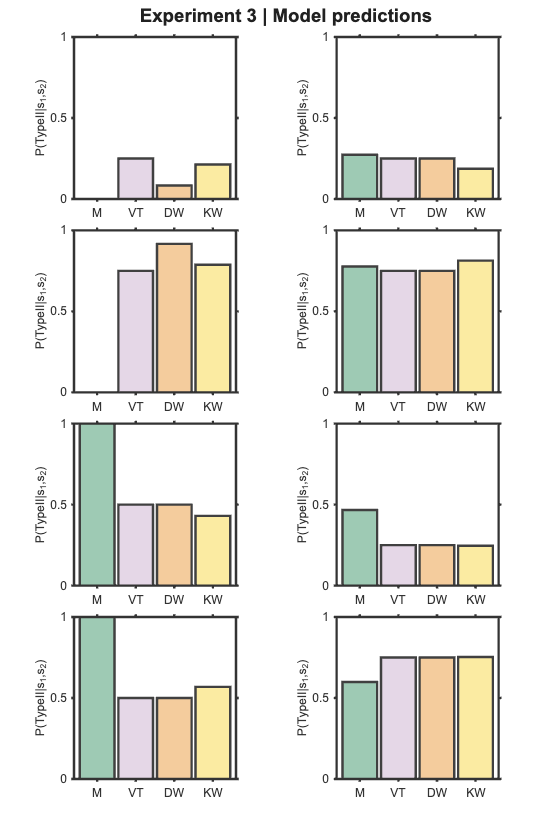

%% Exp3 posterior weights: eight square bar-chart panels
% User-set prediction parameters on the positive scale (AFTER exp).
% ce is retained for consistency with the models; it does not change w.
clear; clc;
paramValues.mentalizing = 5;         % [ce]
paramValues.vt = [5 1];              % [ce, n]
paramValues.dw = [5 1 5];           % [ce, n, e]
paramValues.kw = [5 1];             % [ce, n]
trialsToPlot = 1:8;                 % Alternatively, 9:16
saturationScale = 0.82;             % 1 = supplied colors; lower = less saturated
saveFigure = true;
projectRoot = fileparts(fileparts(fileparts(mfilename('fullpath'))));
outputDir = fullfile(projectRoot, 'figures', 'exp3_posteriors');

names = {'mentalizing','vt','dw','kw'};
labels = {'M','VT','DW','KW'};
counts = [1 2 3 2];
for k = 1:4
    validateattributes(paramValues.(names{k}), {'numeric'}, ...
        {'row','real','finite','positive','numel',counts(k)});
end
validateattributes(trialsToPlot, {'numeric'}, ...
    {'row','numel',8,'integer','>=',1,'<=',16});
assert(numel(unique(trialsToPlot))==8, 'Select eight distinct trials.');
validateattributes(saturationScale, {'numeric'}, {'scalar','real','finite','>=',0,'<=',1});

%% Formulas from /Users/foxxis/Desktop/HBI/exp3/src/models
% Keep all 16 entries: KW swaps its conflict-trial weights in the second block.
posteriorWeight = zeros(16,4);
m = [0 0 1 1 .2735507 .7765487 .4667553 .5992063];
posteriorWeight(:,1) = [m m]';
n = paramValues.vt(2);
d = 2+2*n;
v = [1/d (1+2*n)/d .5 .5 1/d (1+2*n)/d 1/d (1+2*n)/d];
posteriorWeight(:,2) = [v v]';
n = paramValues.dw(2); e = paramValues.dw(3);
d = 2+2*n; de = 2+2*n*e;
v = [1/de (1+2*n*e)/de .5 .5 1/d (1+2*n)/d 1/d (1+2*n)/d];
posteriorWeight(:,3) = [v v]';
n = paramValues.kw(2);
eargain  = 1.675676; footgain = 1.027027;
d = 2+(eargain+footgain)*n;
v = [1/d (1+(eargain+footgain)*n)/d ...
     (1+footgain*n)/d (1+eargain*n)/d ...
     1/(2+2*eargain*n) (1+2*eargain*n)/(2+2*eargain*n) ...
     1/(2+2*footgain*n) (1+2*footgain*n)/(2+2*footgain*n)];
posteriorWeight(:,4) = [v v([1 2 4 3 5 6 7 8])]';
assert(all(isfinite(posteriorWeight(:))) && ...
    all(posteriorWeight(:)>=0 & posteriorWeight(:)<=1));

%% Preserve the supplied hues and brightness while reducing HSV saturation
baseColors = [ ...
    0.584 0.792 0.686; ... 
    0.898 0.827 0.906; ... 
    0.957 0.765 0.541; ... 
    0.984 0.906 0.561];    
hsvColors = rgb2hsv(baseColors);
hsvColors(:,2) = saturationScale*hsvColors(:,2);
colors = hsv2rgb(hsvColors);

fig = figure('Color','w','Name','Experiment 3 posterior predictions', ...
    'Position',[100 40 680 1000]);
set(fig,'DefaultAxesFontName','Arial','DefaultTextFontName','Arial');
layout = tiledlayout(fig,4,2,'TileSpacing','compact','Padding','compact');
title(layout,'Experiment 3 | Model predictions','FontName','Arial', ...
    'FontSize',14,'FontWeight','bold');
% MATLAB tiles are row-major; use column-wise trial order as in the reference.
panelOrder = [1 5 2 6 3 7 4 8];
for panel = 1:8
    trial = trialsToPlot(panelOrder(panel));
    ax = nexttile(layout);
    bar(ax,1:4,posteriorWeight(trial,:),.9,'FaceColor','flat', ...
        'CData',colors,'EdgeColor',[.25 .25 .25],'LineWidth',1.8);
    set(ax,'FontName','Arial','FontSize',9,'Box','on','TickDir','out', ...
    'LineWidth',1.8,'XColor',[.2 .2 .2],'YColor',[.2 .2 .2], ...
    'XGrid','off','YGrid','off');
    xlim(ax,[.4 4.6]); ylim(ax,[0 1]);
    xticks(ax,1:4); xticklabels(ax,labels); yticks(ax,[0 .5 1]);
    ylabel(ax,'P(TypeII|s_1,s_2)','Interpreter','tex', ...
        'FontName','Arial','FontSize',9);
    pbaspect(ax,[1 1 1]);
end
if saveFigure
    if ~exist(outputDir,'dir'), mkdir(outputDir); end
    stem = sprintf('exp3_trials_%d_to_%d',trialsToPlot(1),trialsToPlot(end));
    exportgraphics(fig,fullfile(outputDir,[stem '.png']),'Resolution',300);
    exportgraphics(fig,fullfile(outputDir,[stem '.pdf']),'ContentType','vector');
    savefig(fig,fullfile(outputDir,[stem '.fig']));
    save(fullfile(outputDir,[stem '.mat']),'paramValues','posteriorWeight', ...
        'trialsToPlot','colors','saturationScale');
end